clc; clear; close all;
%Parameters
a0 = 1.30;
a1 = -7 * 10^-2;
a2 = 1.10;
a3 = 1.18; 
a4 = 7.80 ; 
a5 = 0.00; 
a6 = -0.20; 
a7 = 2.4 * 10^-2; 
a8 = 2.53 * 10^-2;
a9 = 0.00;
a10 = 0.00; 
a11 = 3.57 * 10^-3; 
a12 = 0.00;
a13 = 0.00; 

gamma = 10

gamma = 10

alpha = linspace(-8,8,40)

alpha =    -8.0000   -7.5897   -7.1795   -6.7692   -6.3590   -5.9487   -5.5385   -5.1282   -4.7179   -4.3077   -3.8974   -3.4872   -3.0769   -2.6667   -2.2564   -1.8462   -1.4359   -1.0256   -0.6154   -0.2051    0.2051    0.6154    1.0256    1.4359    1.8462    2.2564    2.6667    3.0769    3.4872    3.8974    4.3077    4.7179    5.1282    5.5385    5.9487    6.3590    6.7692    7.1795    7.5897    8.0000


%Fz = 1 

hold on

Fz = linspace(1,5,40)

Fz =     1.0000    1.1026    1.2051    1.3077    1.4103    1.5128    1.6154    1.7179    1.8205    1.9231    2.0256    2.1282    2.2308    2.3333    2.4359    2.5385    2.6410    2.7436    2.8462    2.9487    3.0513    3.1538    3.2564    3.3590    3.4615    3.5641    3.6667    3.7692    3.8718    3.9744    4.0769    4.1795    4.2821    4.3846    4.4872    4.5897    4.6923    4.7949    4.8974    5.0000


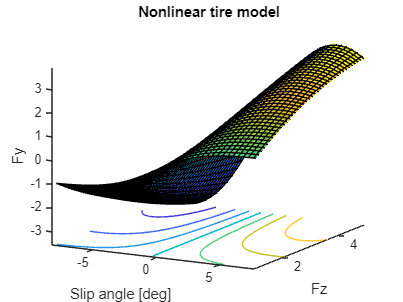

[alpha,Fz] = meshgrid(alpha,Fz); 

    Sh = (a8.*gamma) + (a9.*Fz) + a10;
    E = (a6.*Fz) + a7;
    x = alpha + Sh; 
    C = a0; 
    D = (a1.*Fz + a2).*Fz; 
    BCD = a3.*sin(2.*atan(Fz./a4)).*(1-a5.*abs(gamma));
    B = BCD./(C.*D); 
    Sv = (a11.*Fz.*gamma) + (a12.*Fz) + a13; 
    Fy = D.*sin(C.*atan(B.*x)-E.*(B.*x-atan(B.*x)))+Sv;
    %plot(alpha,Y,'-');


surfc(alpha,Fz,Fy)

    title('Nonlinear tire model');
    xlabel('Slip angle [deg]');
    ylabel('Fz');
    zlabel('Fy');

    %legend({'Fz = 1[kN]', 'Fz = 2[kN]', 'Fz = 3[kN]', 'Fz = 4[kN]', 'Fz = 5[kN]'},...
        %'Location','best'); 


